# Linear Control Design II - Group Work Problem Module 13

## Description

Consider the airplane model (MIMO model).

% System matrices:
A = [-0.0558 -0.9968  0.0802  0.0415;
    0.598  -0.115  -0.0318  0;
    -3.050   0.388  -0.4650  0;
    0       0.0805  1       0]

A =       -0.0558      -0.9968       0.0802       0.0415
        0.598       -0.115      -0.0318            0
        -3.05        0.388       -0.465            0
            0       0.0805            1            0


B = [0.00729 1e-5; -0.475 0.123; 0.153 1.063; 0 0]

B =       0.00729        1e-05
       -0.475        0.123
        0.153        1.063
            0            0


C = [0 1 0 0;0 0 0 1]

C =      0     1     0     0
     0     0     0     1


D = [0;0];
damp(A)

                                                                        
         Pole              Damping       Frequency       Time Constant  
                                       (rad/TimeUnit)     (TimeUnit)    
                                                                        
 -3.29e-02 + 9.47e-01i     3.48e-02       9.47e-01          3.04e+01    
 -3.29e-02 - 9.47e-01i     3.48e-02       9.47e-01          3.04e+01    
 -5.63e-01                 1.00e+00       5.63e-01          1.78e+00    
 -7.28e-03                 1.00e+00       7.28e-03          1.37e+02    


**Problem 1**

Is the system observable? Is it detectable?

% Fill in your answer here:

Mo=obsv(A,C);
if rank(Mo)==size(A,1)
    disp('The System is observable')
else
    disp('The System is not observable')
end

The System is observable


**Problem 2**

In module 10 multivariable state feedback controller for the aircraft. The closed-loop continuous eigenvalues were:


$$\lambda=\left\{\matrix{-0.5\cr-0.6\cr-0.5\pm0.5j}\right.$$


Design a discrete time observer for the system and use the sampling period $Ts=0.1\text{s}$. Find the observer gain matrix **L** that assigns the eigenvalues of the estimation error dynamics to be 4-5 times faster than those of the closed-loop system (in continuous time). Use the Matlab function *place()* and remember that an observer can be designed by solving the dual problem of controller design.

Check the eigenvalues of the estimation error.

% Fill in your answer here:
Ts = 0.1;
[F,G] = c2d(A,B,Ts)

F =       0.99025     -0.09852     0.008162    0.0041326
     0.059681      0.98554   -0.0028461   0.00012395
     -0.29562     0.052509      0.95329  -0.00061999
    -0.014699     0.010396     0.097656      0.99998


G =     0.0031376  -0.00017599
    -0.047181      0.01206
     0.013694      0.10412
    0.0005229    0.0052907


lambda = [-0.5 -0.6 -0.5-0.5j -0.5+0.5j];
P_obsv_d = exp(5*lambda*Ts);

L=place(F',C', P_obsv_d)'

L =       0.14764     -0.46951
      0.30553     -0.12927
     -0.32822        1.305
    -0.025207      0.59473


log(eig(F-L*C))/Ts

ans =          -2.5 +        2.5i
         -2.5 -        2.5i
         -2.5 +          0i
           -3 +          0i


**Problem 3**

Add the observer to the open loop Simulink model of the aircraft and carry out a simulation with the function on Figure 1 at both inputs, but one at a time. Plot the states, the state estimates and the estimation error.

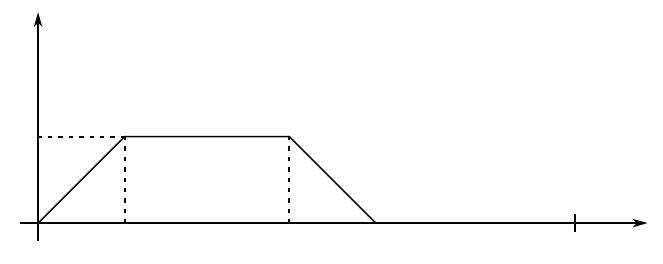


$$Figure\,1: Input\,signal\,for\,the\,closed\,loop\,system.$$


% Fill in your answer here:
t = 0:0.1:150;

% Input funtion of interest
U1 = t(1:50)*0.0175/5;
U2 = t(51:150)*0+0.0175;
U3 = 0.0175-U1;
% Spacing
U4 = 0*t(1:100);
U5 = 0*t(1:800);
U6 = 0*t(1001:end);
U7 = 0*t(301:end);

u1 = [U4 U1 U2 U3 U7];
u2 = [U5 U1 U2 U3 U6];

inp = [t' u1' u2'];
xh0 = [0.015;-0.03;-0.08;-0.7]';
x0 = [0 0 0 0]';
sim('Mdl_13_OpenLoop_w_observer.slx',t(end),[],inp)
pTime = 5;
lbl = labels(4,2,2,{'$\beta$ (Slip Slide angle)','$r$ (Yaw rate)',...
    '$p$ (Roll rate)','$\varphi$ (Roll angle)'},{'rad','rad/s','rad/s','rad'},...
    {'rad','rad'},{});

lbl = struct with fields:
      time: 'Time $[s]$'
         u: {'$u_1(t)$'  '$u_2(t)$'}
     u_vec: '$\mathbf{u}(t)$'
        uU: {'$u_1(t)$ $[rad]$'  '$u_2(t)$ $[rad]$'}
    uUnits: {' $[rad]$'  ' $[rad]$'}
         x: {'$x_1(t)$'  '$x_2(t)$'  '$x_3(t)$'  '$x_4(t)$'}
        xh: {'$\hat{x}_1(t)$'  '$\hat{x}_2(t)$'  '$\hat{x}_3(t)$'  '$\hat{x}_4(t)$'}
     x_vec: '$\mathbf{x}(t)$'
    xh_vec: '$\mathbf{\hat{x}}(t)$'
        xN: {'$\beta$ (Slip Slide angle)'  '$r$ (Yaw rate)'  '$p$ (Roll rate)'  '$\varphi$ (Roll angle)'}
        xU: {'$x_1(t)$ $[rad]$'  '$x_2(t)$ $[rad/s]$'  '$x_3(t)$ $[rad/s]$'  '$x_4(t)$ $[rad]$'}
       xhU: {'$\hat{x}_1(t)$ $[rad]$'  '$\hat{x}_2(t)$ $[rad/s]$'  '$\hat{x}_3(t)$ $[rad/s]$'  '$\hat{x}_4(t)$ $[rad]$'}
    xUnits: {' $[rad]$'  ' $[rad/s]$'  ' $[rad/s]$'  ' $[rad]$'}
         y: {'$y_1(t)$'  '$y_2(t)$'}
        yh: {'$\hat{y}_1(t)$'  '$\hat{y}_2(t)$'}


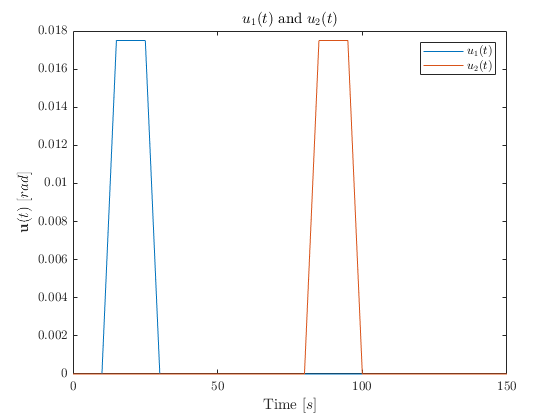

figure, plot(t_olwo, y_olwo.signals(6).values),xlabel(lbl.time),ylabel([lbl.u_vec lbl.uUnits{1}])
title([lbl.u{1} ' and ' lbl.u{2}]),legend(lbl.u{1}, lbl.u{2})

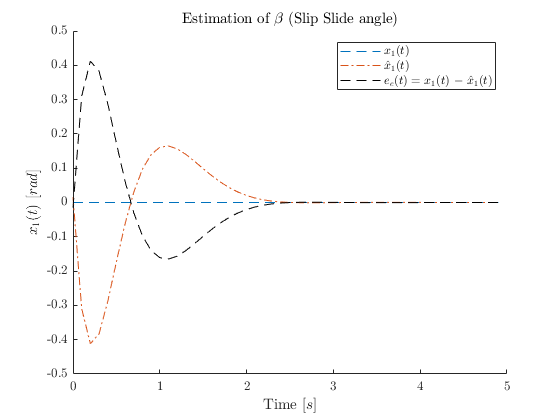

figure, hold on, num = 1;
plot(t_olwo(t_olwo<pTime), y_olwo.signals(2).values((t_olwo<pTime),num),'--') % x1
plot(t_olwo(t_olwo<pTime), y_olwo.signals(4).values((t_olwo<pTime),num),'-.')% x1_h
plot(t_olwo(t_olwo<pTime), y_olwo.signals(5).values((t_olwo<pTime),num),'k--')% e = x1-x1_h
e = ['$e_e(t) =$ ' lbl.x{num} ' $-$ ' lbl.xh{num}];
title(['Estimation of ' lbl.xN{num}]), legend(lbl.x{num},lbl.xh{num},e),
xlabel(lbl.time), ylabel(lbl.xU{num})

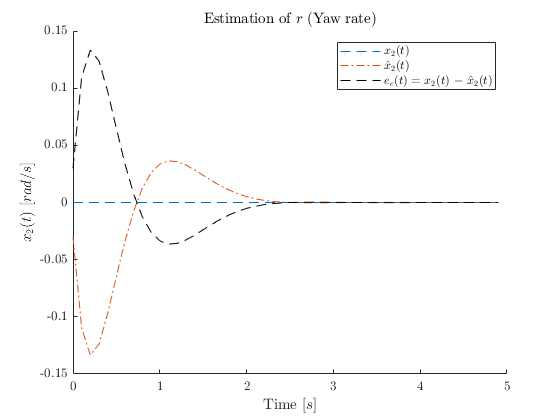

figure, hold on, num = 2;
plot(t_olwo(t_olwo<pTime), y_olwo.signals(2).values((t_olwo<pTime),num),'--') % x1
plot(t_olwo(t_olwo<pTime), y_olwo.signals(4).values((t_olwo<pTime),num),'-.')% x1_h
plot(t_olwo(t_olwo<pTime), y_olwo.signals(5).values((t_olwo<pTime),num),'k--')% e = x1-x1_h
e = ['$e_e(t) =$ ' lbl.x{num} ' $-$ ' lbl.xh{num}];
title(['Estimation of ' lbl.xN{num}]), legend(lbl.x{num},lbl.xh{num},e),
xlabel(lbl.time), ylabel(lbl.xU{num})

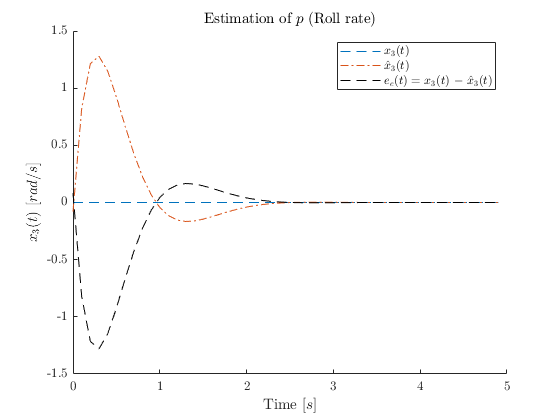

figure, hold on, num = 3;
plot(t_olwo(t_olwo<pTime), y_olwo.signals(2).values((t_olwo<pTime),num),'--') % x1
plot(t_olwo(t_olwo<pTime), y_olwo.signals(4).values((t_olwo<pTime),num),'-.')% x1_h
plot(t_olwo(t_olwo<pTime), y_olwo.signals(5).values((t_olwo<pTime),num),'k--')% e = x1-x1_h
e = ['$e_e(t) =$ ' lbl.x{num} ' $-$ ' lbl.xh{num}];
title(['Estimation of ' lbl.xN{num}]), legend(lbl.x{num},lbl.xh{num},e),
xlabel(lbl.time), ylabel(lbl.xU{num})

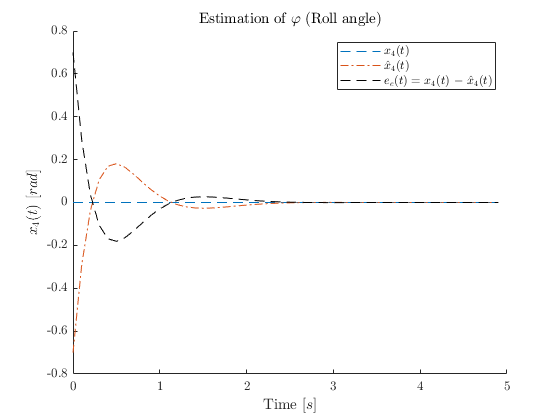

figure, hold on, num = 4;
plot(t_olwo(t_olwo<pTime), y_olwo.signals(2).values((t_olwo<pTime),num),'--') % x1
plot(t_olwo(t_olwo<pTime), y_olwo.signals(4).values((t_olwo<pTime),num),'-.')% x1_h
plot(t_olwo(t_olwo<pTime), y_olwo.signals(5).values((t_olwo<pTime),num),'k--')% e = x1-x1_h
e = ['$e_e(t) =$ ' lbl.x{num} ' $-$ ' lbl.xh{num}];
title(['Estimation of ' lbl.xN{num}]), legend(lbl.x{num},lbl.xh{num},e),
xlabel(lbl.time), ylabel(lbl.xU{num})

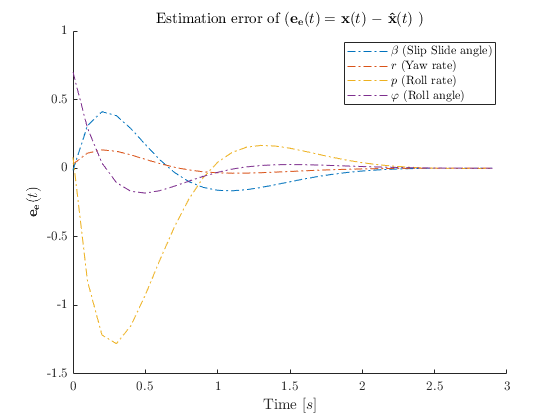

figure, hold on
plot(t_olwo(t_olwo<3), y_olwo.signals(5).values(t_olwo<3,:),'-.')
title(['Estimation error $(\mathbf{e_e}(t) =$ ' lbl.x_vec ' $-$ ' lbl.xh_vec ' $)$' ])
legend(lbl.xN), xlabel(lbl.time), ylabel('$\mathbf{e_e}(t)$')

**Problem 4**

Add the discrete controller designed in the module 10 to the Simulink model and instead of using the true states of the system, use their estimates provided by the observer. Carry out simulations and plot the states, the state estimates, the estimation error, the outputs and the control signals. Compare the performance of the closed-loop systems with and without the observer.

% Fill in your answer here:
l_cld = exp(lambda*Ts);
K = place(F,G,l_cld);
h = 1;

sim('Mdl_13_CloseLoop_w_observer.slx')



**Problem 5**

Do the estimations obtained from the observer depend on how good the controller is? Can we estimate any of the states if the system is very fast or unstable?

% Fill in your answer here:



**Problem 6**

Repeat Problem 2-4 using the controller with integral action.

% Fill in your answer here:

